% AAE532 EXAM 2 PROBLEM 1
% TOMOKI KOIKE
clear all; close all; clc;

% Set constants 
mu_e = 4.0000e5;
R_e  = 6400;
mu_m = 5.00e3;
R_m  = 1500;
D_e2m = 4.0000e5;

D_m2sc = 50*R_m

D_m2sc = 75000

r_m2sc = D_m2sc

r_m2sc = 75000

r_sc2e = D_e2m - D_m2sc

r_sc2e = 325000

r_m2e  = D_e2m;

DT = mu_m / r_m2sc^2;  % dominant term

DT = 8.8889e-07

DPT = mu_e / r_sc2e^2;  % direct perturbing term

DPT = 3.7870e-06

IDPT = mu_e / r_m2e^2;  % indirect perturbing term

IDPT = 2.5000e-06

PT = DPT - IDPT;

PT = 1.2870e-06

rddot = PT - DT;

rddot = 3.9809e-07

p0 = 4*R_m

p0 = 6000

e0 = 1/sqrt(3)

e0 = 0.5774


% i
v_e = sqrt(2*mu_m / p0)

v_e = 1.2910

% ii
r0 = p0;
a0 = p0 / (1 - e0^2)

a0 = 9.0000e+03

h0 = sqrt(mu_m * p0)

h0 = 5.4772e+03

v0 = vis_viva(r0, a0, mu_m)

v0 = 1.0541

FPA0 = acosd(h0 / r0 / v0)

FPA0 = 30.0000


rN = r0;
hN = 8200;
EnN = 1/6;
pN = hN^2 / mu_m

pN = 13448

aN = -mu_m / 2 / EnN 

aN = -15000

eN = sqrt(1 - pN / aN)

eN = 1.3771

vN = vis_viva(rN, aN, mu_m)

vN = 1.4142

FPAN = acos_dbval(hN / rN / vN, "deg")

FPAN =    14.8993  -14.8993


FPAN = FPAN(FPAN > 0)

FPAN = 14.8993

% iii
v0vec = v0 * [sind(FPA0), cosd(FPA0)]

v0vec =     0.5270    0.9129


vNvec = vN * [sind(FPAN), cosd(FPAN)]

vNvec =     0.3636    1.3667


dvvec = vNvec - v0vec

dvvec =    -0.1634    0.4538


dv = norm(dvvec)

dv = 0.4823


v0vec_vnb = v0 * [1, 0]

v0vec_vnb =     1.0541         0


vNvec_vnb = vN * [cosd(FPA0 - FPAN), -sind(FPA0 - FPAN)]

vNvec_vnb =     1.3654   -0.3684


dvvec_vnb = vNvec_vnb - v0vec_vnb

dvvec_vnb =     0.3113   -0.3684


alpha = acosd(dot(v0vec, dvvec) / v0 / dv)

alpha = 49.8051

TAN = acosd(1/eN * (pN / rN - 1))

TAN = 25.6599

domega = 90 - TAN

domega = 64.3401

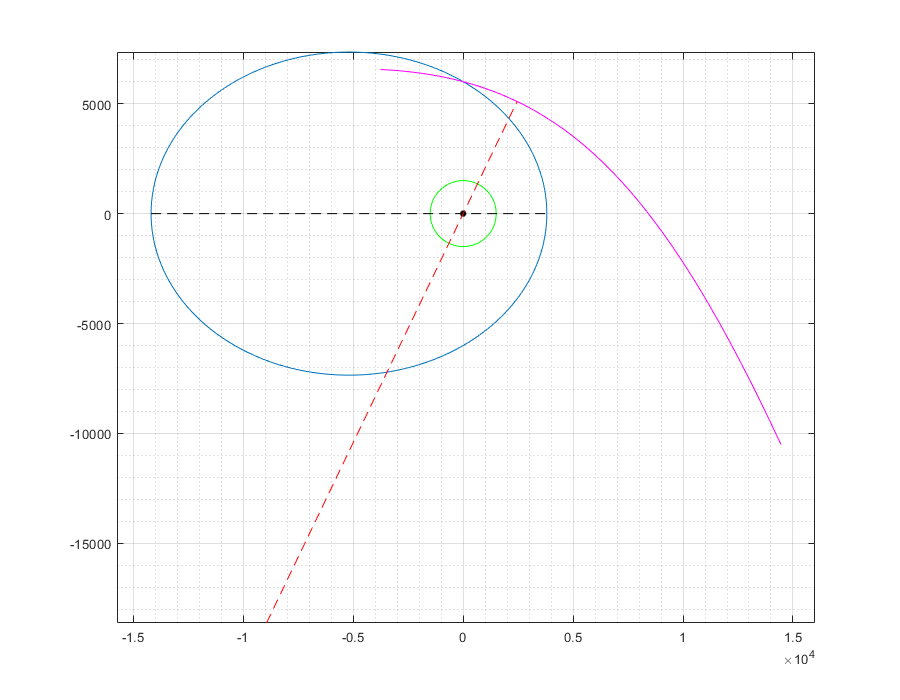

% old orbit
angles = 0:0.01:2*pi;
RR = p0 ./ (1 + e0*cos(angles)); XX = RR.*cos(angles); YY = RR.*sin(angles);

% new orbit
ang = -pi/5:0.01:pi/1.5;
RR_new = pN ./ (1 + eN*cos(ang - deg2rad(domega)));
XX_new = RR_new.*cos(ang);
YY_new = RR_new.*sin(ang);
rp_new = -aN*(eN-1); ra_new = -aN*(eN);
rp_vec = rp_new*[cosd(domega), sind(domega)];
ra_vec = ra_new*[cosd(domega+180), sind(domega+180)];

Xmoon = R_m*cos(angles); Ymoon = R_m*sin(angles);
fig = figure("Renderer","painters","Position",[10, 10, 900, 700]);
plot(XX,YY)
hold on; grid on; grid minor; box on; axis equal; 
% plot(r1vec_i(1), r1vec_i(2), '.r', 'MarkerSize', 20)
plot(0,0,'.k', 'MarkerSize', 15)
plot(Xmoon, Ymoon, '-g')
plot(XX_new, YY_new, '-m')
ra = a0*(1+e0); rp = a0*(1-e0);
plot([-ra, rp], [0, 0], '--k')
plot([ra_vec(1), rp_vec(1)],[ra_vec(2), rp_vec(2)], '--r')
hold off